## **Finite Difference Method**

clc
clear

syms a c h x

% No of elements
e = 3;
% No of Nodal points
n =e+1;

f = 4*x^2 - 2*x -4; % Source term
% Source vector Initialization 
f_x = sym(zeros(n, 1));

exact_sol_f = -2*x^2+x;

% numerical values for a, c, and h
a_num = 1;
c_num = -2;
% domain of X
x0 = 0;
xn = 1;
% Element length
h_num = (xn - x0) / e;

% At nodel point the value of x
X = (x0:h_num:xn)';

% U coefficient matrix
U = diag((c-(2*a)/h^2)*ones(1, n)) + ...
     diag((a/h^2)*ones(1, n-1), 1) + ...
     diag((a/h^2)*ones(1, n-1), -1);
%disp(U);

% U coefficient matrix Numerical
U_num = subs(U, [a, c, h], [a_num, c_num, h_num]);
%disp(U_num);

% Calculate f(x) for each x value symbolically and store in the vector
for i = 1:n
    f_x(i) = subs(f, x, X(i));
end
% Source vector numerical
%disp(f_x);

% Dirichlet Boundary Conditions

U_D_bc=U_num;
fx_D_bc=f_x;

% Boundary Conditions1
u0 = 0;
U_D_bc(1,:)= [1,zeros(1, n-1)];  %u0 = 0
fx_D_bc(1) = u0;  % RHS of equation

% Boundary Conditions2
un = -1;
U_D_bc(end,:)= [zeros(1, n-1), 1];  %un=-1
fx_D_bc(end) = un;  % RHS of equation

% for finding inverse I'm using My TDMA inverse function
U_D_bc_inv = InverseTDMA(U_D_bc)

The inverse for the given matrix Tridigonal matrix, computed using the TDMA, is:


U_D_bc_inv =     1.0000         0         0         0
    0.5643   -0.0627   -0.0282    0.2539
    0.2539   -0.0282   -0.0627    0.5643
         0         0         0    1.0000



%The Solution of Dirichlet B.C. using FDM is =
u_D_bc = double(U_D_bc_inv*fx_D_bc);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Dirichlet B.C. using FDM is")

The Solution of Dirichlet B.C. using FDM is


Table1 = table(X, u_D_bc, 'VariableNames', {'Nodal point', 'u'});
disp(Table1);

    Nodal point       u    
    ___________    ________

            0             0
      0.33333       0.11111
      0.66667      -0.22222
            1            -1



disp("-------------------------------------------------------------")

-------------------------------------------------------------


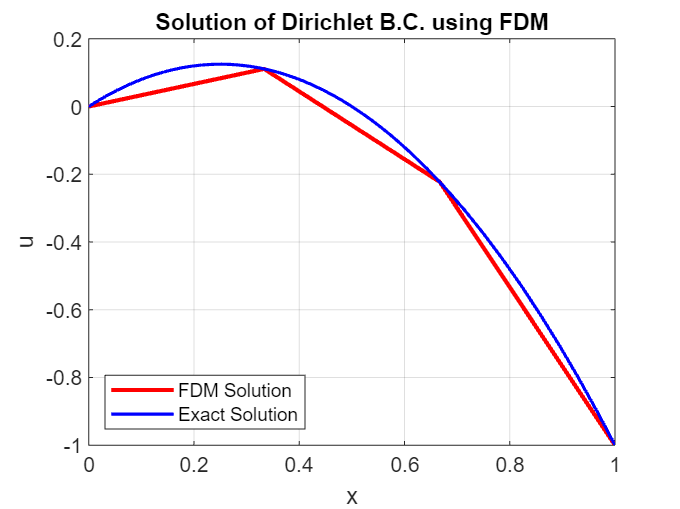


%Plot the FDM Solution and the actual solution
figure;
plot(X, u_D_bc, "r", "LineWidth", 2, "DisplayName", "FDM Solution"); 
hold on;
fplot(x, exact_sol_f, [0 1], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FDM");
legend('Location', 'southwest');
grid on;


%-----------------------------------------------------------------
% Neumann boundary Conditions

% U coefficient matrix  and f_x is little modifed
du_dx = -3; % at end point x = 1

U_mod = U;
U_mod(end,end-1) = 2*U(end,end-1);
U_mod_num = subs(U_mod, [a, c, h], [a_num, c_num, h_num]);

f_x_mod = f_x;
f_x_mod(end) = f_x(end) - ((2*a_num*du_dx)/h_num);

% Neumann Boundary Conditions
U_n_bc=U_mod_num;
fx_n_bc=f_x_mod;



% Boundary Conditions1
u0 = 0;
U_n_bc(1,:)= [1,zeros(1, n-1)];  %u0 = 0
fx_n_bc(1) = u0;  % RHS of equation

% for finding inverse I'm using My TDMA inverse function
U_n_bc_inv = InverseTDMA(U_n_bc)

The inverse for the given matrix Tridigonal matrix, computed using the TDMA, is:


U_n_bc_inv =     1.0000         0         0         0
    0.6822   -0.0758   -0.0573   -0.0258
    0.5159   -0.0573   -0.1274   -0.0573
    0.4643   -0.0516   -0.1146   -0.1016



%The Solution of Dirichlet B.C. using FDM is =
u_n_bc = double(U_n_bc_inv*fx_n_bc);% u at nodal points

disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Neumann B.C. using FDM with Phantom Node is");

The Solution of Neumann B.C. using FDM with Phantom Node is


Table2 = table(X, u_n_bc, 'VariableNames', {'Nodal point', 'u'});
disp(Table2);

    Nodal point       u    
    ___________    ________

            0             0
      0.33333       0.11111
      0.66667      -0.22222
            1            -1



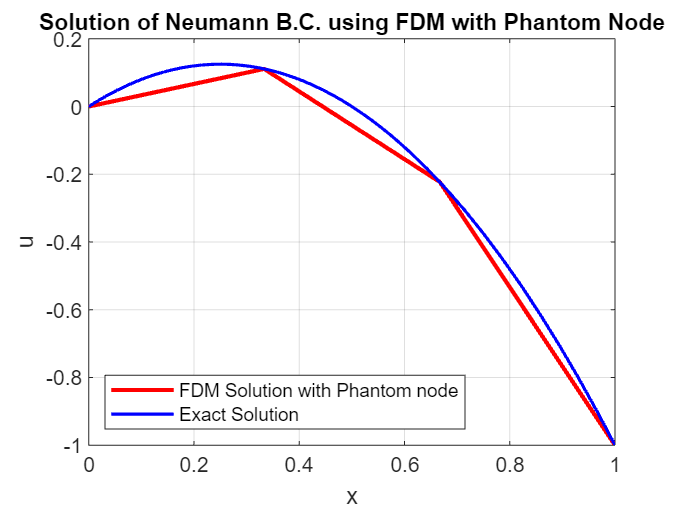



%Plot the FDM Solution and the actual solution
figure;
plot(X, u_n_bc, "r", "LineWidth", 2, "DisplayName", "FDM Solution with Phantom node"); 
hold on;
fplot(x, exact_sol_f, [0 1], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Neumann B.C. using FDM with Phantom Node");
legend('Location', 'southwest');
grid on;

function [X] = InverseTDMA(T)
    [n, ~] = size(T);

    % Check if T is tridiagonal
    for a = 1:n
        for b = 1:n
            if a ~= b && a ~= b - 1 && a ~= b + 1 && T(a, b) ~= 0
                disp('The given matrix is not a tridiagonal matrix');
                %n = 0;
                return;
            end
        end
    end

    B = eye(n); % Initialize B as an identity matrix

    % Decompose T using row operations
    for i = 2:n
        T(i, i - 1) = T(i, i - 1) / T(i - 1, i - 1);
        T(i, i) = T(i, i) - T(i, i - 1) * T(i - 1, i);
    end

    % Perform row operations on B
    for j = 1:n
        for i = 2:n
            B(i, j) = B(i, j) - T(i, i - 1) * B(i - 1, j);
        end
    end

    X = zeros(n, n); % Initialize X as a zero matrix

    % Back substitution to find the inverse matrix X
    for p = 1:n
        X(n, p) = B(n, p) / T(n, n); % Find the last element of each column
        for q = n - 1:-1:1
            X(q, p) = (B(q, p) - T(q, q + 1) * X(q + 1, p)) / T(q, q); % Compute elements in reverse order
        end
    end

    disp('The inverse for the given matrix Tridigonal matrix, computed using the TDMA, is:');
end


